clear;
load data.mat;
load output.mat;

m = size(x, 1);
x = [ones(m, 1) x];
n = size(x, 2);
alpha = 1e-6;
theta = rand(n, 1);
theta_old = theta;
iters = 10;

thetas = [];
thetas = [thetas; theta'];
for i = 1:iters
    theta = theta + alpha*(x'*(y - (x*theta)));
    thetas = [thetas; theta'];
end

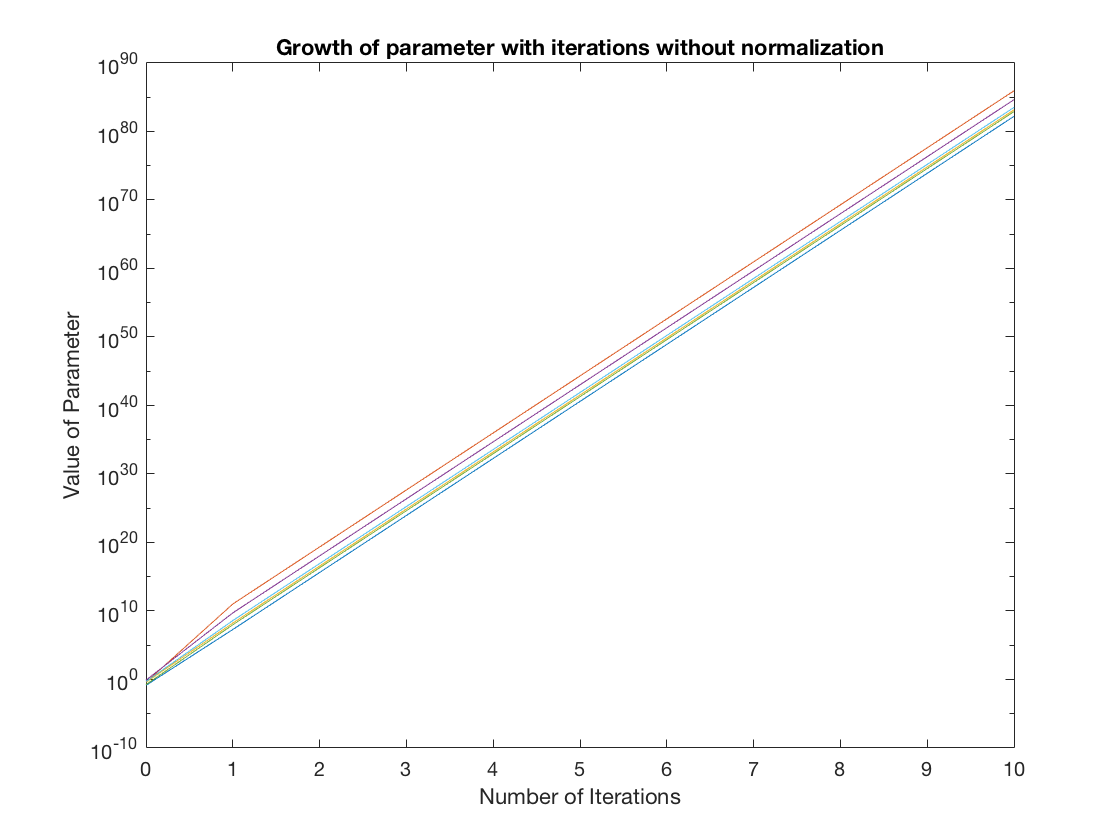

iterations = (0:iters)';
figure;
semilogy(iterations, abs(thetas(:, 1)));
hold on;
for i = 2:n
    semilogy(iterations, abs(thetas(:, i)));
end
ylabel('Value of Parameter');
xlabel('Number of Iterations');
title('Growth of parameter with iterations without normalization');

iters = 1000;
for i = 2:n
    x(:, i) = (x(:, i) - mean(x(:, i)))/std(x(:, i));
end
y = (y - mean(y))/std(y);

theta = theta_old;

err_regression = [];
theta_regression = [];

err_regression = [err_regression; (1/(2*m))*sum((y-x*theta).^2)];
theta_regression = [theta_regression; theta'];

for i = 1:iters
    theta = theta + alpha*(1/m)*(x'*(y - (x*theta)));
    err_regression = [err_regression; (1/(2*m))*sum((y-x*theta).^2)];
    theta_regression = [theta_regression; theta'];
end

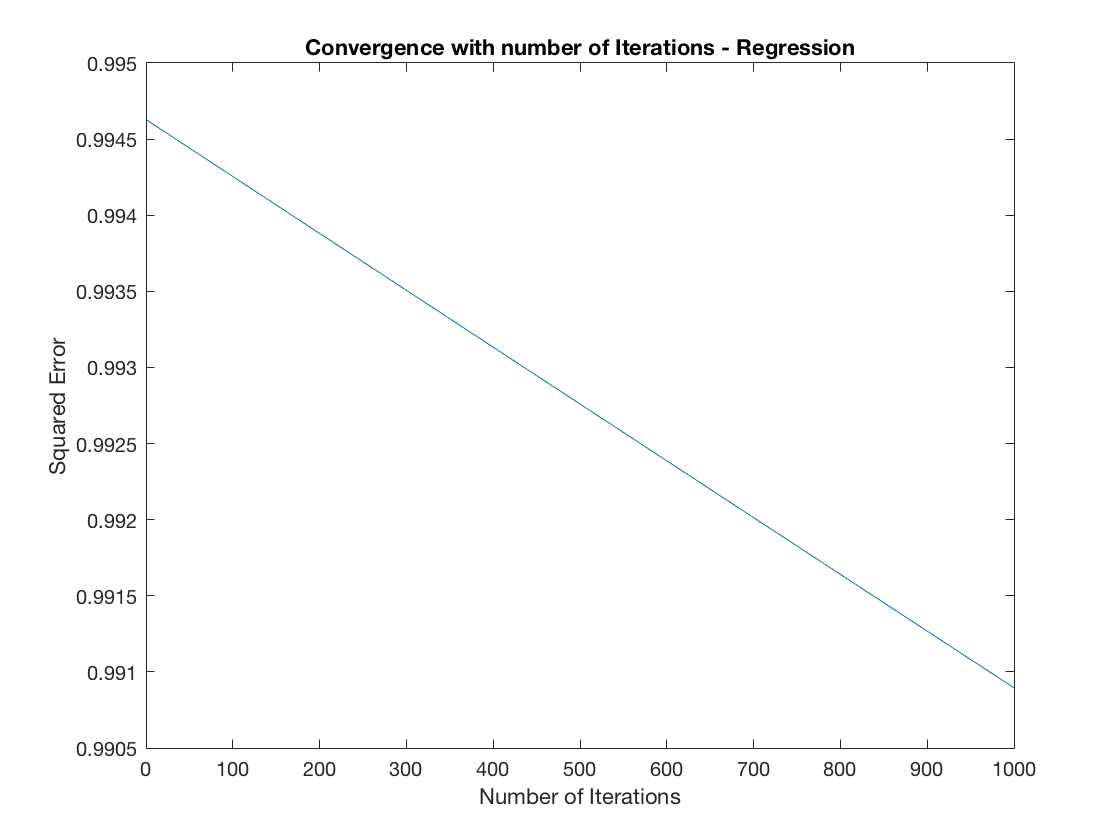

iterations = (0:iters)';
figure;
plot(iterations, err_regression);
hold on;
xlabel('Number of Iterations');
ylabel('Squared Error');
title('Convergence with number of Iterations - Regression');

theta = theta_old;

theta =     0.8147
    0.9058
    0.1270
    0.9134
    0.6324
    0.0975


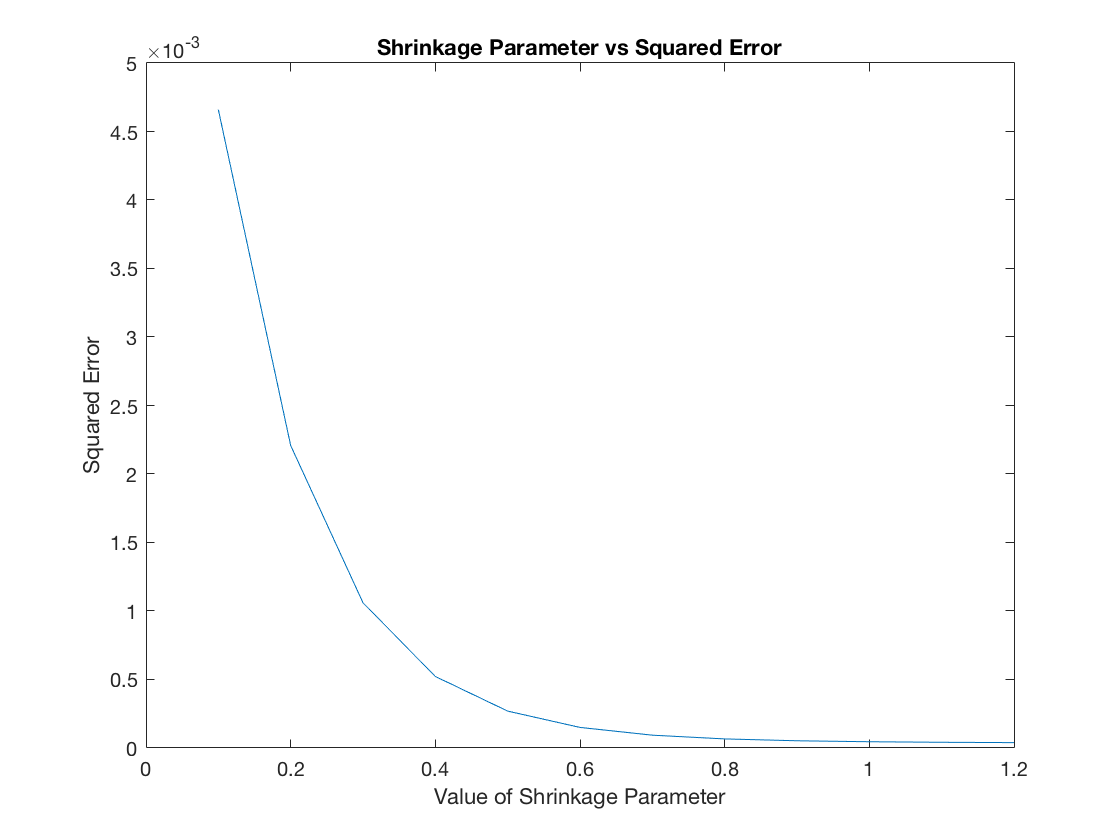



ldas = 0.1:0.1:1.2;
lda_errs = [];


for lda=ldas
    for i = 1:iters
        theta = theta + alpha*(x'*(y - (x*theta))) - alpha*lda*theta;
    end
    lda_errs = [lda_errs; (1/(2*m))*sum((y-x*theta).^2)];
end

figure;
plot(ldas, lda_errs);
xlabel('Value of Shrinkage Parameter')
ylabel('Squared Error')
title('Shrinkage Parameter vs Squared Error')


[j, i] = min(lda_errs);
lda = ldas(i);

theta = theta_old;


theta_ridge = [];
err_ridge = [];

theta_ridge = [theta_ridge; theta'];
err_ridge = [err_ridge; (1/(2*m))*sum((y-x*theta).^2)];

for i = 1:iters
    theta = theta + alpha*(x'*(y - (x*theta))) - alpha*lda*theta;
    theta_ridge = [theta_ridge; theta'];
    err_ridge = [err_ridge; (1/(2*m))*sum((y-x*theta).^2)];
end

theta_bar_plot = [theta_ridge(size(theta_ridge, 1), :)' theta_regression(size(theta_regression, 1), :)']

theta_bar_plot =     0.0000    0.8139
    0.6803    0.9049
   -0.0901    0.1261
    0.4136    0.9124
   -0.0017    0.6317
    0.0011    0.0974


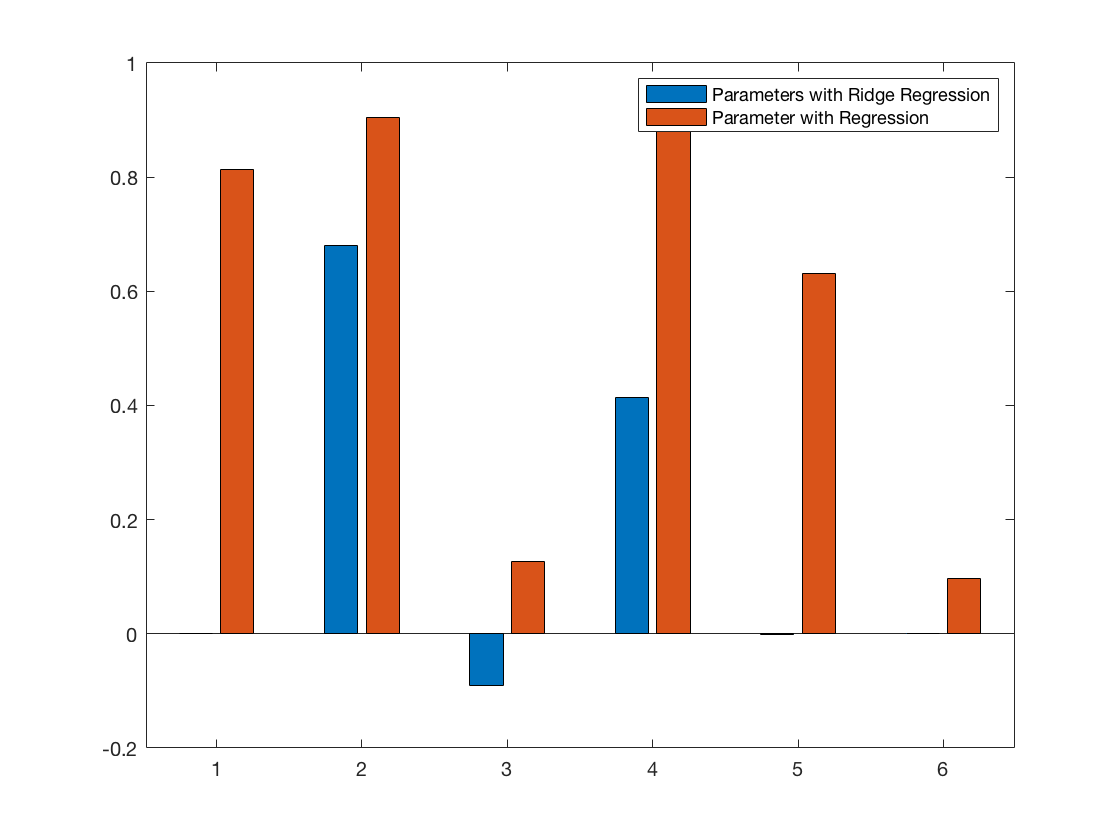

figure;
bar((1:n)', theta_bar_plot);
legend('Parameters with Ridge Regression', 'Parameter with Regression');

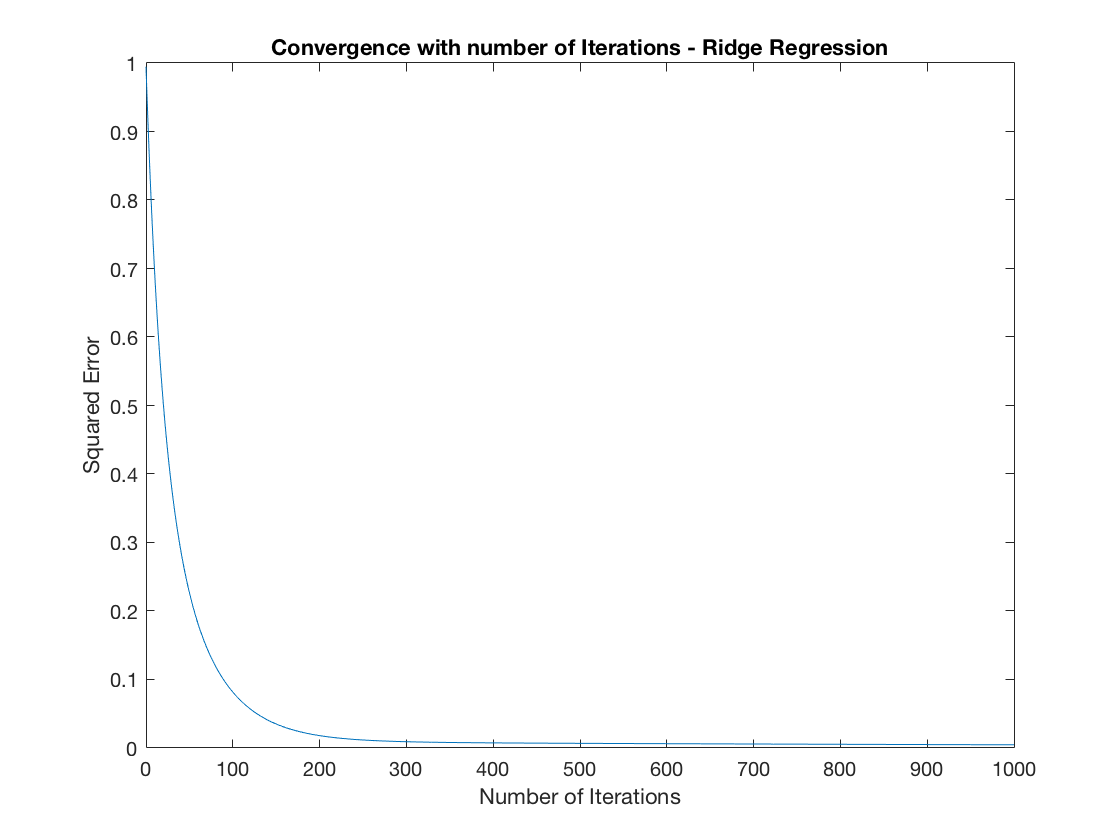

iterations = (0:iters)';
figure;
plot(iterations, err_ridge);
hold on;
xlabel('Number of Iterations');
ylabel('Squared Error');
title('Convergence with number of Iterations - Ridge Regression');

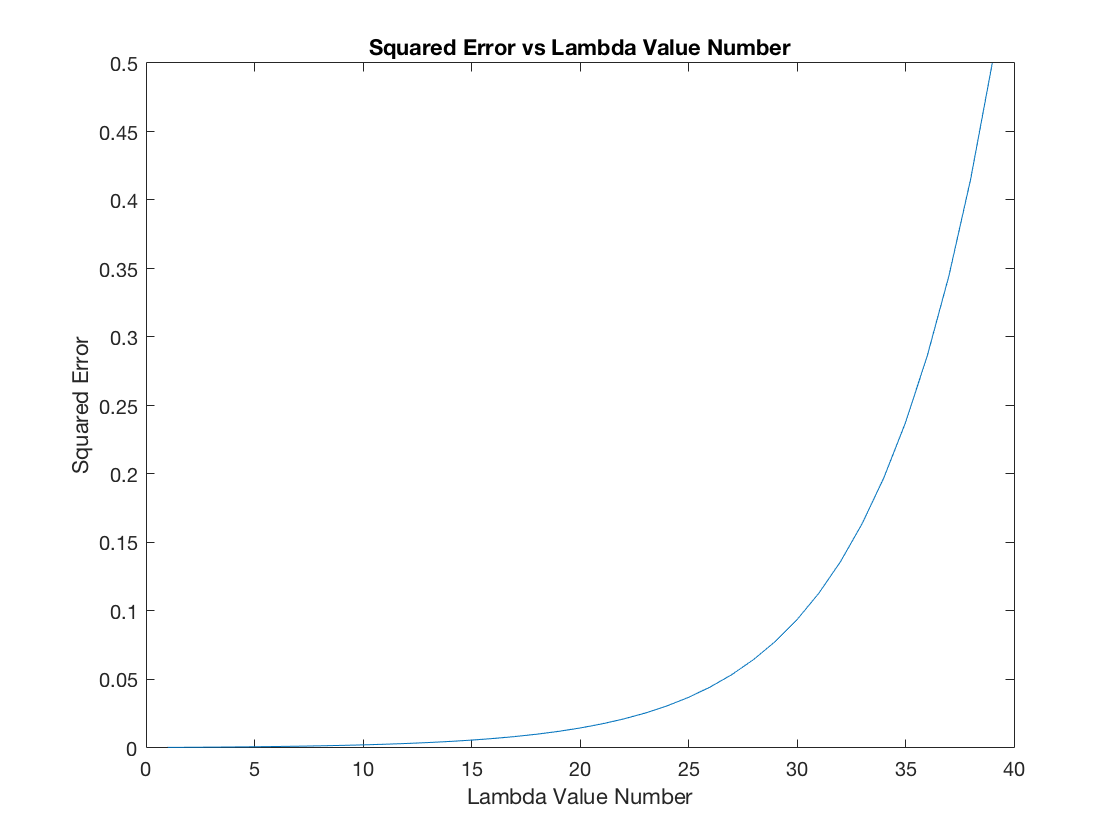

thetas = lasso(x, y);
err_lasso_ldas = [];
for i = 1:size(thetas, 2)
    theta = thetas(:, i);
    err_lasso_ldas = [err_lasso_ldas; (1/(2*m))*sum((y-x*theta).^2)];
end

lda_values = 1:size(err_lasso_ldas);
figure;
plot(lda_values, err_lasso_ldas);
xlabel('Lambda Value Number');
ylabel('Squared Error');
title('Squared Error vs Lambda Value Number');

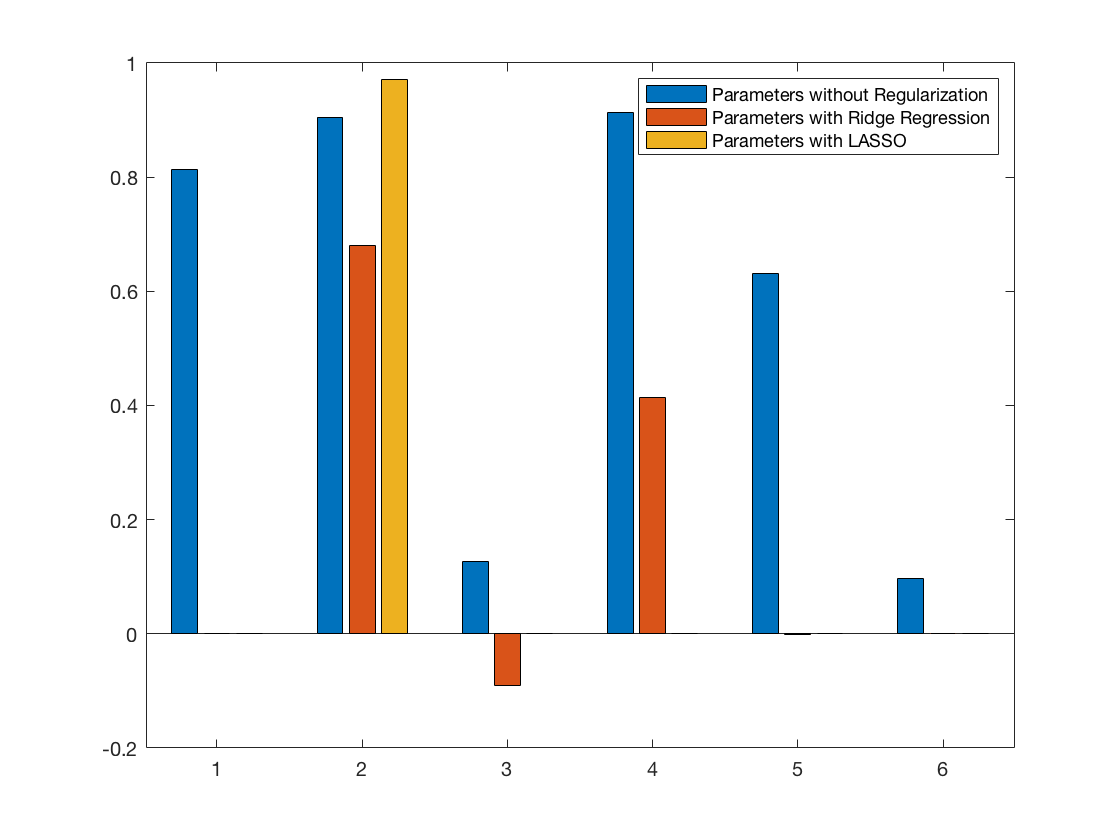


[j, i] = min(err_lasso_ldas);
theta_bar_plot = [theta_regression(size(theta_regression, 1), :)' theta_ridge(size(theta_ridge, 1), :)' thetas(:, i)];
figure;
bar(theta_bar_plot);
legend('Parameters without Regularization', 'Parameters with Ridge Regression', 'Parameters with LASSO');

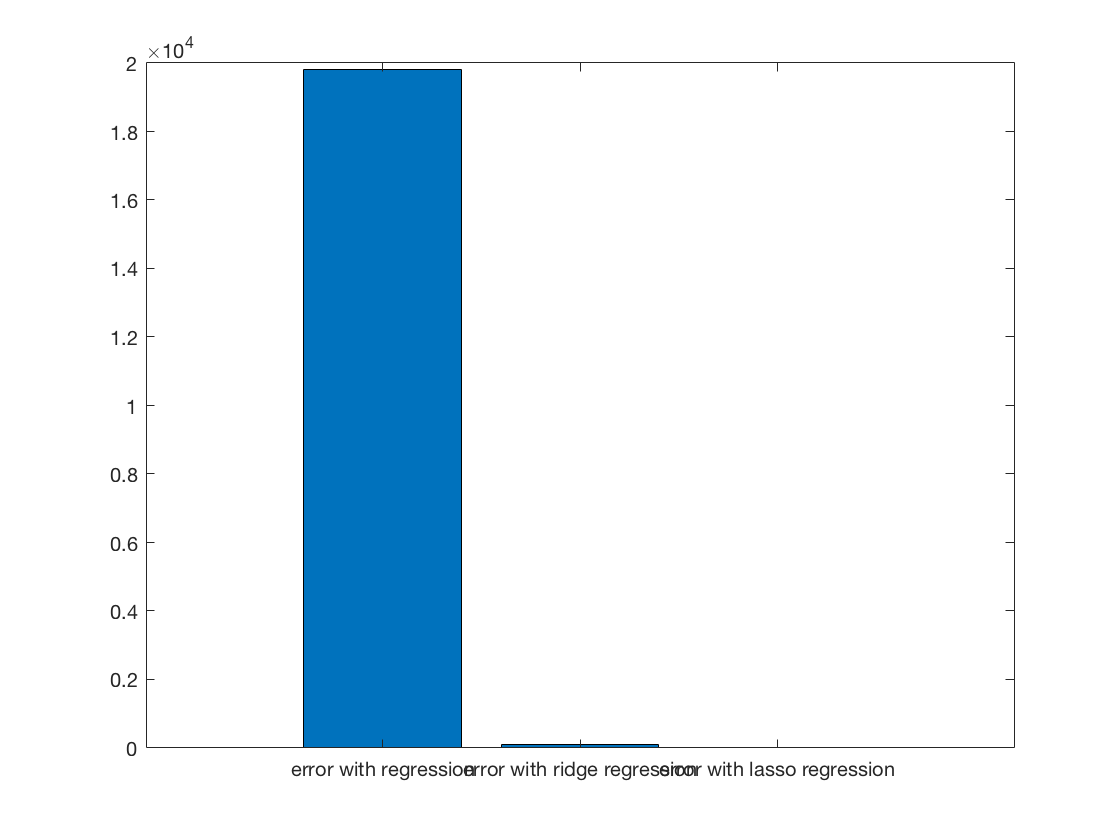

err1 = sum((y - x*theta_regression(size(theta_regression, 1), :)').^2);
err2 = sum((y - x*theta_ridge(size(theta_regression, 1), :)').^2);
err3 = sum((y - x*thetas(:, i)).^2);
name = {'error with regression'; 'error with ridge regression'; 'error with lasso regression'};
error_bar_plot = [err1 err2 err3];
x_axis = [1:3];
figure;
bar(error_bar_plot);
set(gca, 'xticklabel', name);